## Classic Curve Fitting

### Assignment: Exercise 4-2 (Brunton & Kutz, 2019)

Script author: Emmanuel Rodriguez

[emmanueljrodriguez.com](https://emmanueljrodriguez.com/)

Date: 2DEC2023

Location: Renton, Seattle, WA

clear all;

#### Import Data

Temperature data taken over a 24-hour cycle is given:

% Temperature data vector
temp = [75, 77, 76, 73, 69, 68, 63, 59, 57, 55, 54, 52,...
    50, 50, 49, 49, 49, 50, 54, 56, 59, 63, 67, 72]

temp =     75    77    76    73    69    68    63    59    57    55    54    52    50    50    49    49    49    50    54    56    59    63    67    72



% Time vector
t = 1:24; % ';' suppresses the output

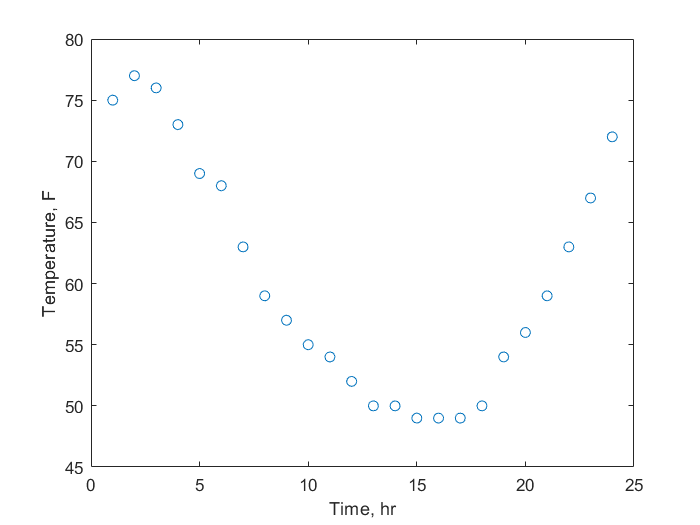

% Visualize the data
plot(t, temp,'o');
xlabel('Time, hr');
ylabel('Temperature, F');

#### Fit the Data with a Parabolic Fit


$$f(x) = Ax^2+Bx+C$$


p = polyfit(t,temp,2) % Polynomial fit, the '2' specifies the 

p =     0.1849   -5.2642   88.2955


% degree of the polynomial; the output vector are the regression
% coefficients

Regression coefficients:


$$A = 0.1849$$



$$B = -5.2642$$



$$C = 88.2955$$



$$f(x) = 0.1849x^2 - 5.2642x + 88.2955$$


Evalute the polynomial at each hour:

temp_poly = polyval(p,t); % Evaluate the poly p at each hour

Plot the results

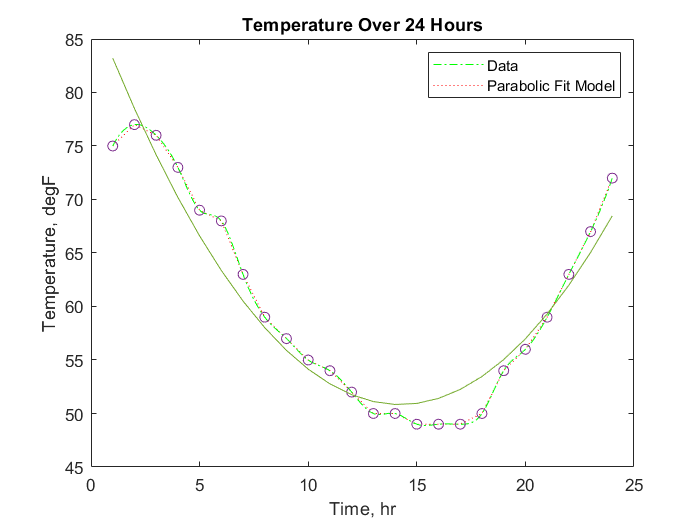

%hold on; % This 'holds' the plot in memory along with the data
plot(t,temp,'o',t,temp_poly);
legend('Data', 'Parabolic Fit Model');
title('Temperature Over 24 Hours');
xlabel('Time, hr');
ylabel('Temperature, degF');
hold on;

#### Calculate the $E_2$ Error

The $E_2$ error is known as the *least-squares error*, or the $\ell_2$-norm which is the Euclidean distance between two points (i.e., the vector).

Note: In machine learning everything is represented in terms of vectors; hence, the reason for expressing the difference between things in terms of vectors.


$$E_2(f)=\left( \frac{1}{n} \sum^{n}_{k=1} \left| f(x_k) - y_k \right|^2 \right)^{(1/2)}$$


E2 = (1/length(temp)*sum(abs(temp_poly - temp).^2)).^(1/2)

E2 = 2.6799

% Recall: 'temp_poly' is the polynomial evaluated

Equivalently:


$$E_2(f)=\left( \frac{1}{n}\sum^{n}_{k=1} \left| \beta_1 x_k^2 + \beta_2 x_k +\beta_3 - y_k \right|^2 \right)^{(1/2)}$$


E2eq = (1/length(temp)*sum(abs( p(1)*t.^2 + p(2)*t + p(3) - temp).^2)).^(1/2)

E2eq = 2.6799

The $\ell_2$-norm, or the $E_2$ error is, in simplest terms, the "average" Euclidean distance, or the straight (as the crow flies) distance, between the parabolic fit model and the various data points.

In this exercise, the error is computed to be 2.7, or the model is on average predicting the temperature to be $2.7^{\circ}F$ off than the measured reading.

#### Interpolated Approximation 

Use linear and spline interpolation for the query points $x=1:0.01:24$

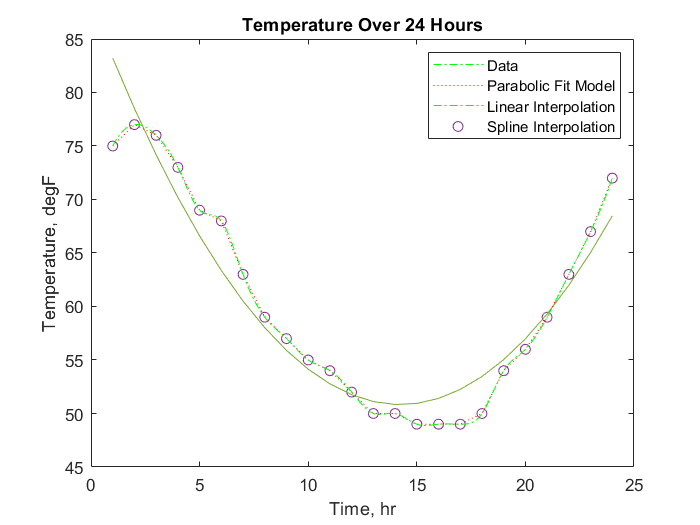

x = 1:0.01:24; % Time vector, or query points

%hold on;
% Linear interpolation
lin_interp = interp1(t,temp,x,'linear');
plot(x,lin_interp,':r');
legend('Data', 'Parabolic Fit Model','Linear Interpolation');

% Spline interpolation
spl_interp = interp1(t,temp,x,'spline');
plot(x,spl_interp,'-.g');
legend('Data', 'Parabolic Fit Model','Linear Interpolation','Spline Interpolation');

### Alternative Linear Regression Procedure

#### Least-Squares Line (Brunton & Kutz, 2019, p. 165)

An alternative to using the `polyfit` function, is to perform least-squares fitting, in which the error $E_2$ is found by **minimizing the sum**:


$$E_2(f) = \sum^{n}_{k=1} \left| f(x_k) - y_k \right|^2 = \sum^{n}_{k=1} (\beta_1 x_k^2 + \beta_2 x_k + \beta_3 - y_k)^2$$


Recall: Minimizing a function requires finding where the slope of the function is zero, i.e., where the **derivative of the function is zero**, or what the value of $\beta$ is when $E(\beta )$ is at a minimum. 

% Use the symbolic math toolbox to determine the derivatives
syms beta1 beta2 beta3 x y
E2Fun = (beta1*x^2 + beta2*x + beta3 - y)^2 % Define function

$$E2Fun = {\left(\beta_{1}\,x^{2}+\beta_{2}\,x+\beta_{3}-y\right)}^{2}$$


E2Funb1 = symfun(E2Fun,beta1) % Create symbolic function as a function of beta1

$$E2Funb1(beta1) = {\left(\beta_{1}\,x^{2}+\beta_{2}\,x+\beta_{3}-y\right)}^{2}$$

dE2db1 = symfun(diff(E2Funb1),beta1) % Find derivative with respect to beta1

$$dE2db1(beta1) = 2\,x^{2}\,\left(\beta_{1}\,x^{2}+\beta_{2}\,x+\beta_{3}-y\right)$$


E2Funb2 = symfun(E2Fun,beta2)

$$E2Funb2(beta2) = {\left(\beta_{1}\,x^{2}+\beta_{2}\,x+\beta_{3}-y\right)}^{2}$$

dE2db2 = symfun(diff(E2Funb2),beta2)

$$dE2db2(beta2) = 2\,x\,\left(\beta_{1}\,x^{2}+\beta_{2}\,x+\beta_{3}-y\right)$$


E2Funb3 = symfun(E2Fun,beta3)

$$E2Funb3(beta3) = {\left(\beta_{1}\,x^{2}+\beta_{2}\,x+\beta_{3}-y\right)}^{2}$$

dE2db3 = symfun(diff(E2Funb3),beta3)

$$dE2db3(beta3) = 2\,\beta_{1}\,x^{2}+2\,\beta_{2}\,x+2\,\beta_{3}-2\,y$$

Therefore we require the following:

$\frac{\partial E_2}{\partial \beta_1} = 0$: $\sum^{n}_{k=1} 2x^2 (\beta_1 x^2 + \beta_2 x + \beta_3 - y)=0$

$\frac{\partial E_2}{\partial \beta_2} = 0$: $\sum^{n}_{k=1} 2x (\beta_1 x^2 + \beta_2 x + \beta_3 - y)=0$

$\frac{\partial E_2}{\partial \beta_3} = 0$: $\sum^{n}_{k=1} 2\beta_1 x^2 + 2\beta_2 x + 2\beta_3 - 2y = 0$

To minimize the error function $E_2$, in other words to find when the derivative of the objective function is equal to zero, the 'fitminsearch' function may be used.

pa = fminsearch('fitE2min',[1 1 1],[],t,temp); % Performs a minimization 
% of the input function, the E2 error; i.e., it attempts to find
% a local minimum of the input function.
% The [1 1 1] are the initial guess values for the model's regression 
% coefficients \beta_1, \beta_2, and \beta_3, respectively.
% [] no optimization options set.
% This will return new values of the regression coefficients,
% \beta_1, \beta_2, and \beta_3 after the 
% minimization algorithm has been run.

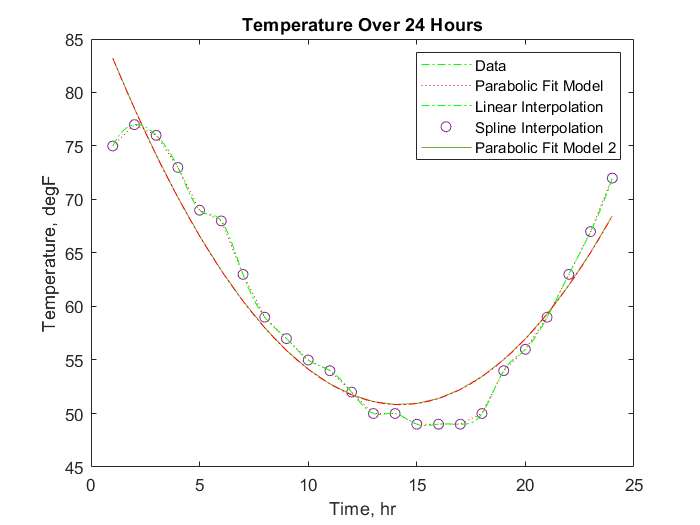

% Evaluate the pa polynomial at the x query points.
x = 1:0.01:24; % Time vector, or query points
temp_poly_pa = polyval(pa,x);

% Plot the two polynomials and the interpolations.
plot(x,temp_poly_pa,'-.r');
legend('Data', 'Parabolic Fit Model','Linear Interpolation','Spline Interpolation', 'Parabolic Fit Model 2');

### Data Fitting of Arbitrary Functions

Fit the data to the cosine function, or the **objective function**:


$$f(x)=\beta_1 cos(\beta_2 x)+ \beta_3$$


Recall: To find the minimum of the function, the root sum of squares error should be minimized. Minimizing the sum requires **differentiation of the objective function**.

Error to minimized:


$$E_2(\beta_1,\beta_2,\beta_3) = \sum^{n}_{k=1}(\beta_1 cos(\beta_2 x)+ \beta_3 - y_k)^2$$


% Use the symbolic math toolbox to determine the derivatives
syms beta1 beta2 beta3 x y
E2Fun = (beta1*cos(beta2*x) + beta3 - y)^2 % Define function

$$E2Fun = {\left(\beta_{3}-y+\beta_{1}\,\cos\left(\beta_{2}\,x\right)\right)}^{2}$$


E2Funb1 = symfun(E2Fun,beta1) % Create symbolic function as a function of beta1

$$E2Funb1(beta1) = {\left(\beta_{3}-y+\beta_{1}\,\cos\left(\beta_{2}\,x\right)\right)}^{2}$$

dE2db1 = symfun(diff(E2Funb1),beta1) % Find derivative with respect to beta1

$$dE2db1(beta1) = 2\,\cos\left(\beta_{2}\,x\right)\,\left(\beta_{3}-y+\beta_{1}\,\cos\left(\beta_{2}\,x\right)\right)$$


E2Funb2 = symfun(E2Fun,beta2)

$$E2Funb2(beta2) = {\left(\beta_{3}-y+\beta_{1}\,\cos\left(\beta_{2}\,x\right)\right)}^{2}$$

dE2db2 = symfun(diff(E2Funb2),beta2)

$$dE2db2(beta2) = -2\,\beta_{1}\,x\,\sin\left(\beta_{2}\,x\right)\,\left(\beta_{3}-y+\beta_{1}\,\cos\left(\beta_{2}\,x\right)\right)$$


E2Funb3 = symfun(E2Fun,beta3)

$$E2Funb3(beta3) = {\left(\beta_{3}-y+\beta_{1}\,\cos\left(\beta_{2}\,x\right)\right)}^{2}$$

dE2db3 = symfun(diff(E2Funb3),beta3)

$$dE2db3(beta3) = 2\,\beta_{3}-2\,y+2\,\beta_{1}\,\cos\left(\beta_{2}\,x\right)$$

Applying the minimizing conditions ($\nabla f(x)=0$) leads to:


$$\frac{\partial{E_2}}{\partial{\beta_1}}=0: \sum^{n}_{k=1} 2\,\mathrm{cos}\left(\beta_2 \,x\right)\,{\left(\beta_3 -y+\beta_1 \,\mathrm{cos}\left(\beta_2 \,x\right)\right)}=0$$



$$\frac{\partial E_2}{\partial \beta_2}=0: \sum^{n}_{k=1} -2\,\beta_1 \,x\,\mathrm{sin}\left(\beta_2 \,x\right)\,{\left(\beta_3 -y+\beta_1 \,\mathrm{cos}\left(\beta_2 \,x\right)\right)} = 0$$



$$\frac{\partial E_2}{\partial \beta_3}=0: \sum^n_{k=1} 2\,\beta_3 -2\,y+2\,\beta_1 \,\mathrm{cos}\left(\beta_2 \,x\right)=0$$


pCosFN = fminsearch('fitE2minCosFN',[.1849 -5.2642 88.2955],[],t,temp) % Performs a minimization 

pCosFN =     1.8636   -5.7398   60.1907


% of the input function, the E2 error; i.e., it attempts to find
% a local minimum of the input function.
% The [1 1 1] are the initial guess values for the model's regression 
% coefficients \beta_1, \beta_2, and \beta_3, respectively.
% [] no optimization options set.
% This will return new values of the regression coefficients,
% \beta_1, \beta_2, and \beta_3 after the 
% minimization algorithm has been run.

Okay, so now we've got our values for the $\beta s$:


$$\beta_1 = -2.1655$$



$$\beta_2 = 11.1011$$



$$\beta_3 = 60.1392$$


Evaluate the function:

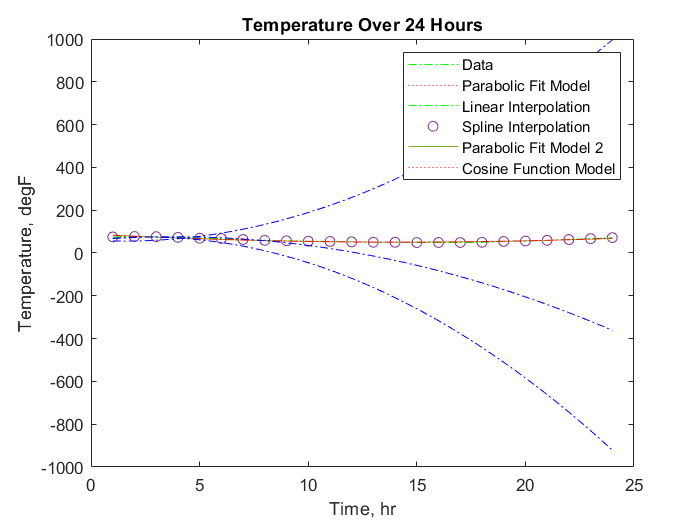

% Evaluate the pa polynomial at the x query points.
x = 1:0.01:24; % Time vector, or query points
temp_poly_pCosFN = polyval(pCosFN,x);

% Plot
plot(x,temp_poly_pCosFN,'-.b');
legend('Data', 'Parabolic Fit Model','Linear Interpolation','Spline Interpolation', 'Parabolic Fit Model 2', 'Cosine Function Model');

Calculate the error:


$$E_2(f)=\left( \frac{1}{n}\sum^{n}_{k=1} \left| \beta_1 cos(\beta_2 x)+ \beta_3 - y_k \right|^2 \right)^{(1/2)}$$


E2eq = (1/length(temp)*sum(abs( pCosFN(1)*t.^2 + pCosFN(2)*t + pCosFN(3) - temp).^2)).^(1/2)

E2eq = 427.7121

E2eqNew = (1/length(temp)*sum(abs( pCosFN(1)*t.^2 + pCosFN(2)*t + pCosFN(3) - temp).^2)).^(1/2)

E2eqNew = 427.7121

The $E_2$ error the cosine function is significant; much greater than the polynomial function.

**Therefore, the parabolic model is a much better fit to the data than the cosine model.**

### **References**

Brunton, S. L., & Kutz, J. N. (2019). *Data-Driven Science and Engineering.* Cambridge: Cambridge University Press.

Chapra, S. C., & Canale, R. P. (2014). *Numerical Methods for Engineers* (7th ed.). New York: McGraw-Hill Higher Education.